# 深入理解nrExtractResources

参考链接：[https://www.mathworks.com/help/releases/R2022b/5g/ref/nrextractresources.html?s_tid=doc_srchtitle#description](https://www.mathworks.com/help/releases/R2022b/5g/ref/nrextractresources.html?s_tid=doc_srchtitle#description)

多天线技术可以实现空分复用，支持多流传输，在多天线的发送和接收就需要做资源映射处理。

在发送端需要支持多流数据向天线的映射。

在接收端需要从天线接收的数据中提取目标资源和目标资源对应的信道估计矩阵H。

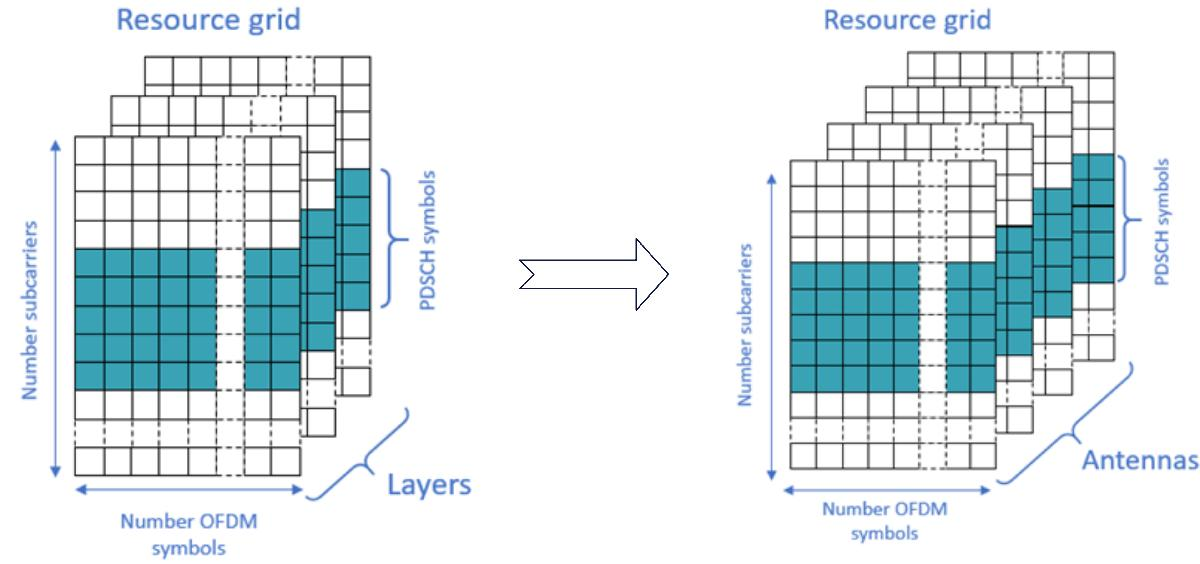

## 1 函数输入和输出

`[re,reind] = nrExtractResources(ind,grid)`

该函数用于从资源数组中提取资源元素。具体的，使用资源元素索引`ind，`从资源数组`grid`中，提取资源元素`re`和元素在资源数组中的索引`reind。`

M: the number of subcarriers

N: the number of OFDM symbols

R: the number of antennas（天线数）

P: the number of antenna ports（发端port数）

**输入：**

`ind`  资源元素索引，其维度为（M*N)-by-P   或者 （M*N)-by-R

`grid` 资源数组，其维度为

- 3-D数组：`M`-by-`N`-by-`R `（发端天线或收端天线创建）

- 4-D数组：`M`-by-`N`-by-`R`-by-`P `（信道估计创建）

**输出：**

`re`  Extracted resource elements

`reind` Indices of extracted resource elements

- 如果grid是3维数组，输出矩阵的维度为(M*N)-by-R 

- 如果grid是4维数组，输出矩阵的维度为(M*N)-by-R-by-P

## 2 函数算法原理

### **2.1 All-Planes Extraction Method**

所有平面元素索引取并集，映射到一个平面。

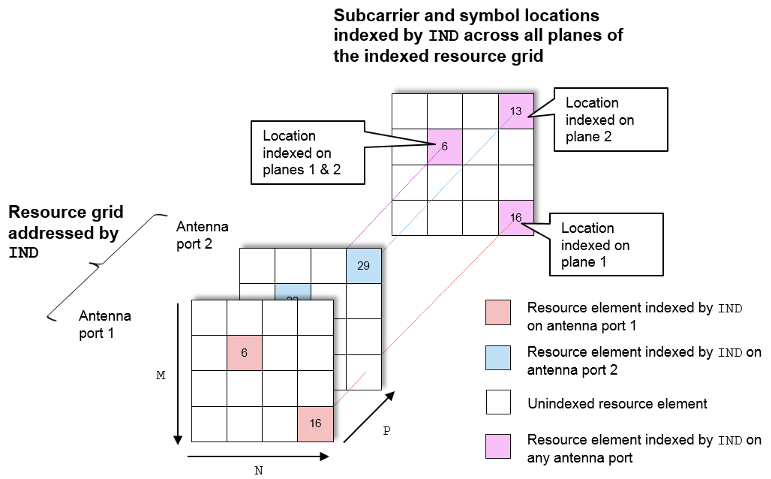

如果grid是3维矩阵，将该平面向天线网格映射，提取天线网格中的元素和元素索引。

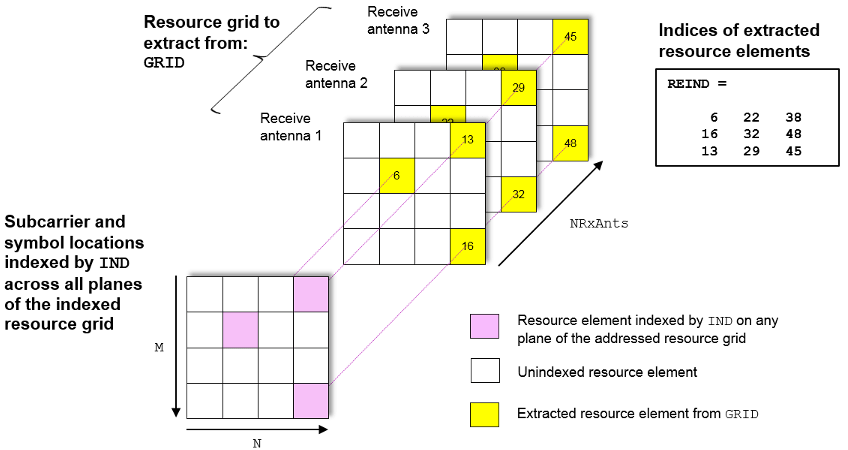

% Case 1
clear;
clc;
close all;

ind = [6 22;16 29];
M = 4;
N = 4;
R = 3;
grid = reshape((1:M*N*R),[M,N,R]);
[re,reind] = nrExtractResources(ind,grid);
displayMat(ind,reind,re)

输入ind：
     6    22
    16    29

输出reind：
     6    22    38
    16    32    48
    13    29    45

输出re：
     6    22    38
    16    32    48
    13    29    45



如果grid是4维矩阵，将该平面向所有port的天线网格映射，提取天线网格中的元素和元素索引。

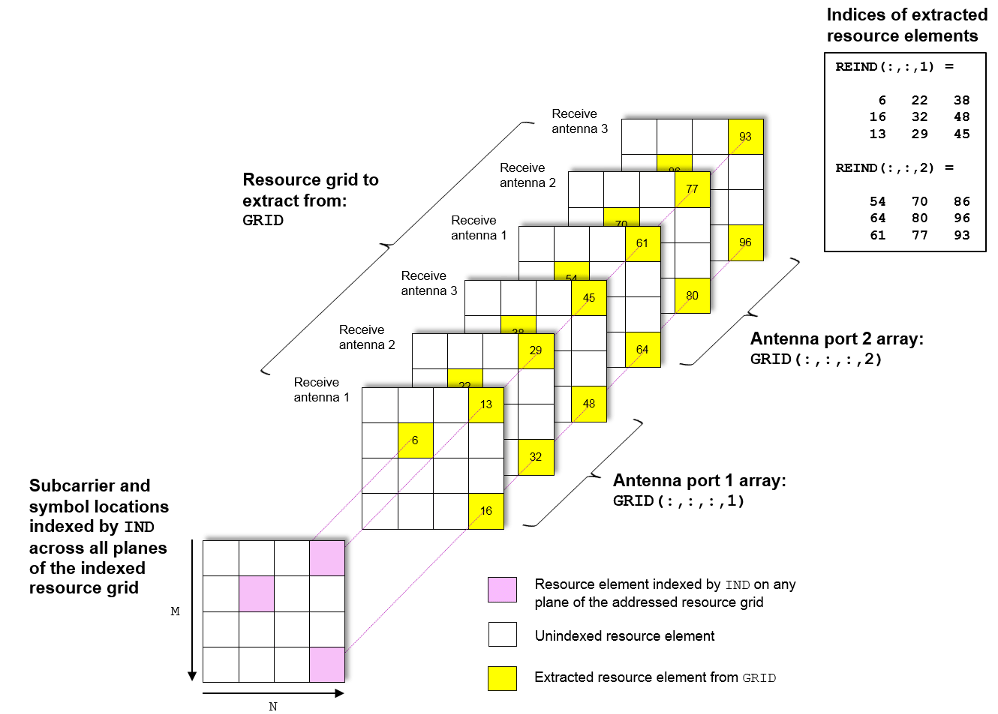

ind = [6 22;16 29];
M = 4;
N = 4;
R = 3;
P = 2;
grid_h = reshape((1:M*N*R*P),[M,N,R,P]);
[re,reind] = nrExtractResources(ind,grid_h);
displayMat(ind,reind,re)

输入ind：
     6    22
    16    29

输出reind：

(:,:,1) =

     6    22    38
    16    32    48
    13    29    45


(:,:,2) =

    54    70    86
    64    80    96
    61    77    93

输出re：

(:,:,1) =

     6    22    38
    16    32    48
    13    29    45


(:,:,2) =

    54    70    86
    64    80    96
    61    77    93



### **2.2 Direct Extraction Method**

直接提取法`ind`的最后一维需要和`grid`的最后一维相同。

使用ind的最后一维的每一维依次去grid的最后一维的每一维去提取元素和计算索引。

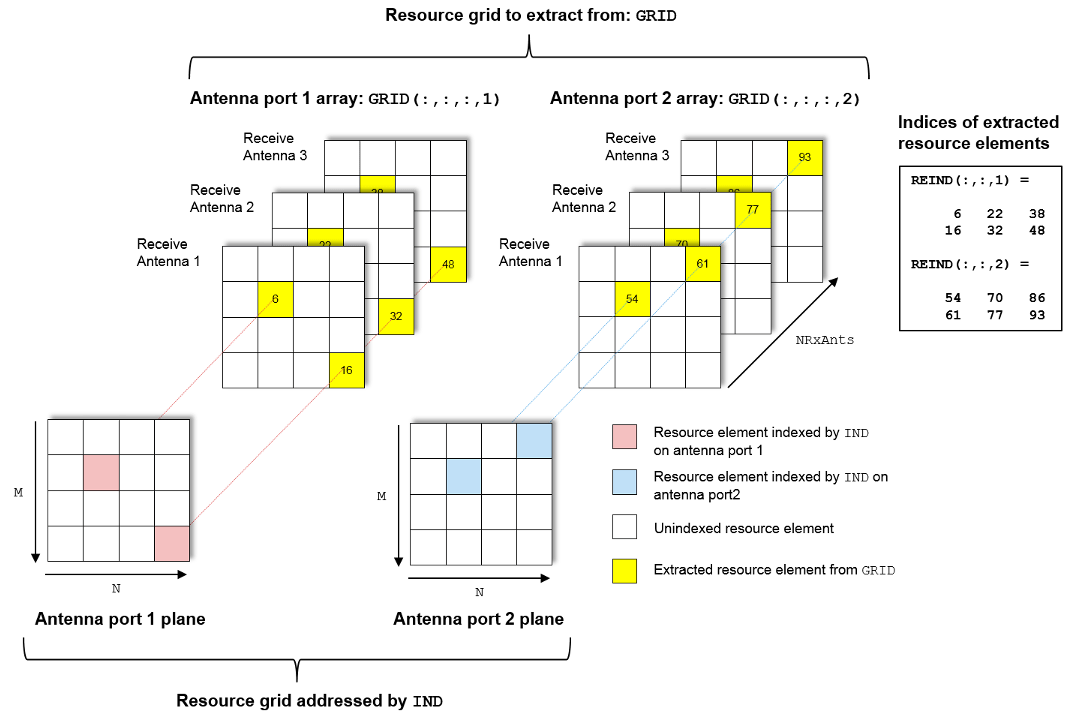

ind = [6 22;16 29];
M = 4;
N = 4;
R = 3;
P = 2;
grid_h = reshape((1:M*N*R*P),[M,N,R,P]);
[re,reind] = nrExtractResources(ind,grid_h,'ExtractionMethod','direct');
displayMat(ind,reind,re)

输入ind：
     6    22
    16    29

输出reind：

(:,:,1) =

     6    22    38
    16    32    48


(:,:,2) =

    54    70    86
    61    77    93

输出re：

(:,:,1) =

     6    22    38
    16    32    48


(:,:,2) =

    54    70    86
    61    77    93



function [] = displayMat(ind,reind,re)
    disp('输入ind：')
    disp(ind)

    disp('输出reind：')
    disp(reind)

    disp('输出re：')
    disp(re)    
end